clear
clc

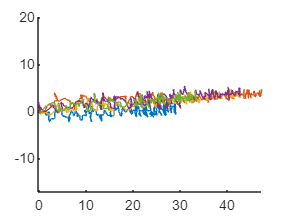

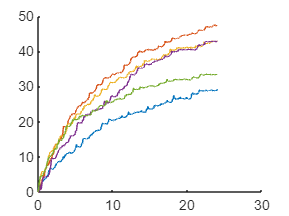

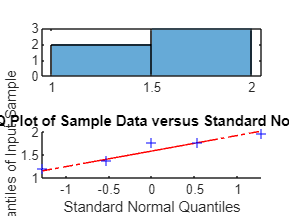

v_sand = 1.6273

std_sand = 0.3133

se_sand = 0.1401

s_sand = struct with fields:
    v_avg: [1.2137 1.9702 1.7811 1.7819 1.3896]


directory = 'data/three-surface-locomotion/sand/no-cycle';
[v_sand, std_sand, se_sand, s_sand] = forward_analysis(directory)

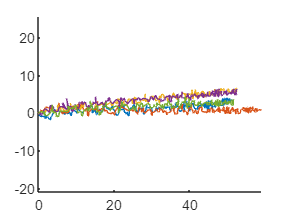

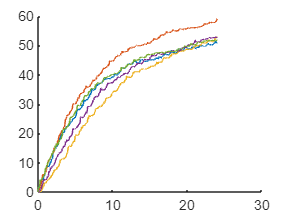

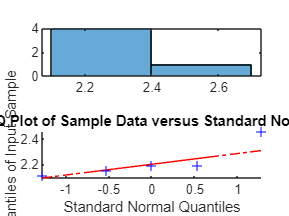

v_sand_05 = 2.2232

std_sand_05 = 0.1367

se_sand_05 = 0.0612

s_sand_05 = struct with fields:
    v_avg: [2.1158 2.4605 2.1948 2.1941 2.1505]



directory = 'data/three-surface-locomotion/sand/05Hz';
[v_sand_05, std_sand_05, se_sand_05, s_sand_05] = forward_analysis(directory)

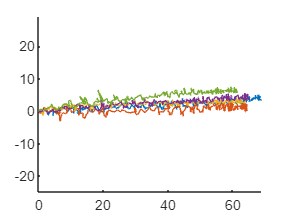

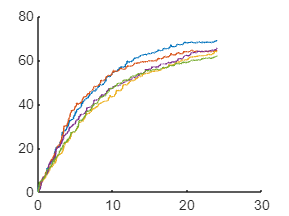

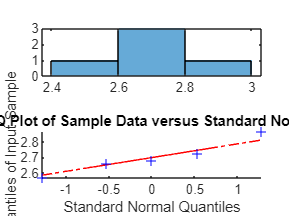

v_sand_09 = 2.6988

std_sand_09 = 0.1113

se_sand_09 = 0.0498

s_sand_09 = struct with fields:
    v_avg: [2.8691 2.6763 2.6575 2.7252 2.5661]



directory = 'data/three-surface-locomotion/sand/09Hz';
[v_sand_09, std_sand_09, se_sand_09, s_sand_09] = forward_analysis(directory)

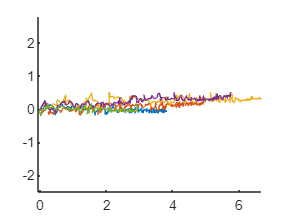

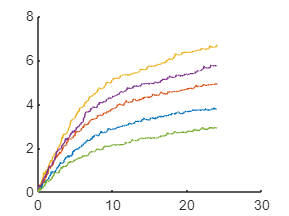

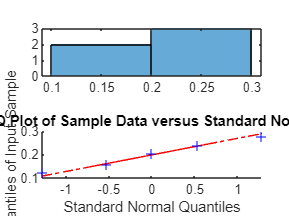

v_sand_no_sled = 0.2001

std_sand_no_sled = 0.0626

se_sand_no_sled = 0.0280

s_sand_no_sled = struct with fields:
    v_avg: [0.1571 0.2049 0.2781 0.2391 0.1214]



directory = 'data/sand-no-sled/no-cycle';
[v_sand_no_sled, std_sand_no_sled, se_sand_no_sled, s_sand_no_sled] = forward_analysis(directory) %notice no sled is in cm

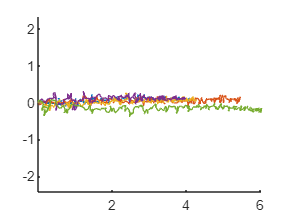

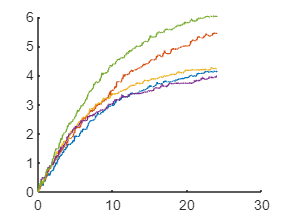

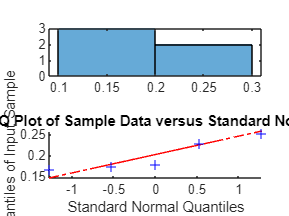

v_sand_05_no_sled = 0.1985

std_sand_05_no_sled = 0.0380

se_sand_05_no_sled = 0.0170

s_sand_05_no_sled = struct with fields:
    v_avg: [0.1725 0.2267 0.1770 0.1655 0.2508]



directory = 'data/sand-no-sled/05Hz';
[v_sand_05_no_sled, std_sand_05_no_sled, se_sand_05_no_sled, s_sand_05_no_sled] = forward_analysis(directory)

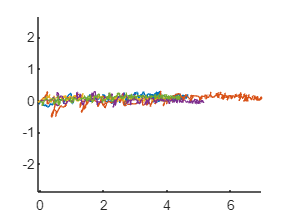

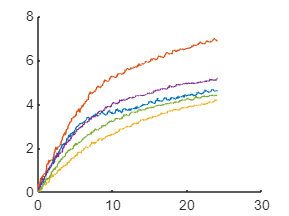

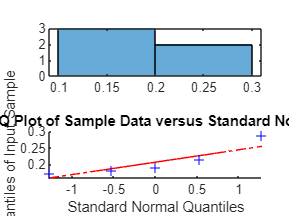

v_sand_09_no_sled = 0.2096

std_sand_09_no_sled = 0.0460

se_sand_09_no_sled = 0.0206

s_sand_09_no_sled = struct with fields:
    v_avg: [0.1909 0.2871 0.1727 0.2149 0.1825]



directory = 'data/sand-no-sled/09Hz';
[v_sand_09_no_sled, std_sand_09_no_sled, se_sand_09_no_sled, s_sand_09_no_sled] = forward_analysis(directory)

v_mean = [v_sand_no_sled*10 v_sand_05_no_sled*10 v_sand_09_no_sled*10
          v_sand v_sand_05 v_sand_09];
v_std = [std_sand_no_sled*10 std_sand_05_no_sled*10 std_sand_09_no_sled*10
         std_sand std_sand_05 std_sand_09];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'Without sledge' 'With sledge'});
set(gca,'XTick',[1 2])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=5.5;
h=5.85 + 0.6;
ylim([0 5])
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex')

lgnd =   Legend (No cycle, 0.5 Hz cycle, 0.9 Hz cycle) with properties:

         String: {'No cycle'  '0.5 Hz cycle'  '0.9 Hz cycle'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.6500
       Position: [0.3669 0.7157 0.5040 0.1710]
          Units: 'normalized'

  Show all properties


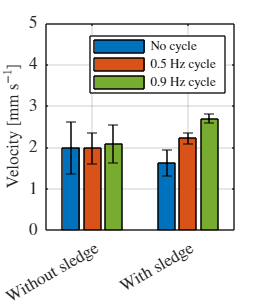

fontsize(10,'points')
fontsize(lgnd,8,'points')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

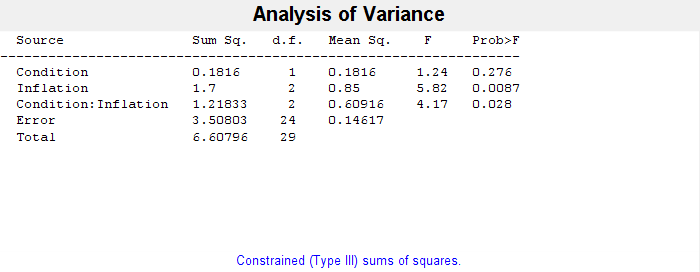

v = [(s_sand_no_sled.v_avg*10)'
     (s_sand_05_no_sled.v_avg*10)'
     (s_sand_09_no_sled.v_avg*10)'
     s_sand.v_avg'
     s_sand_05.v_avg'
     s_sand_09.v_avg'];
conditions   = ["Without", "With"];
inflations = ["0Hz", "0.5Hz", "09Hz"];
condition = strings(30,1);
inflation = strings(30,1);
idx = 1;
for s = 1:2
    for i = 1:3
        for rep = 1:5
            condition(idx) = conditions(s);
            inflation(idx) = inflations(i);
            idx = idx + 1;
        end
    end
end

condition = categorical(condition);
inflation = categorical(inflation);

[p, tbl, stats] = anovan(v, {condition, inflation}, ...
                         'model', 'interaction', ...
                         'varnames', {'Condition', 'Inflation'});

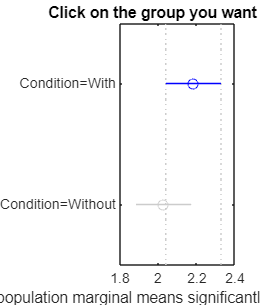

ans =     1.0000    2.0000   -0.1325    0.1556    0.4437    0.2760


multcompare(stats, 'Dimension', 1, 'CriticalValueType','bonferroni')  % Condition

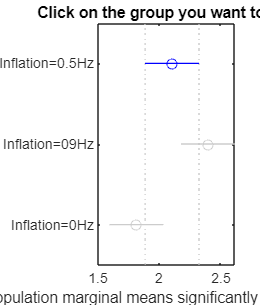

ans =     1.0000    2.0000   -0.7333   -0.2932    0.1468    0.2976
    1.0000    3.0000   -0.1502    0.2898    0.7299    0.3089
    2.0000    3.0000    0.1431    0.5831    1.0231    0.0069


multcompare(stats, 'Dimension', 2, 'CriticalValueType','bonferroni')  % e.g. Bonferroni-corrected

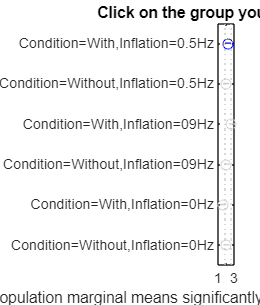

ans =     1.0000    2.0000   -0.5097    0.2380    0.9856    0.9185
    1.0000    3.0000   -1.2233   -0.4757    0.2719    0.3888
    1.0000    4.0000   -0.6205    0.1272    0.8748    0.9946
    1.0000    5.0000   -0.1518    0.5958    1.3435    0.1747
    1.0000    6.0000   -0.5258    0.2218    0.9694    0.9382
    2.0000    3.0000   -1.4613   -0.7137    0.0340    0.0674
    2.0000    4.0000   -0.8584   -0.1108    0.6368    0.9971
    2.0000    5.0000   -0.3898    0.3579    1.1055    0.6795
    2.0000    6.0000   -0.7638   -0.0161    0.7315    1.0000
    3.0000    4.0000   -0.1448    0.6029    1.3505    0.1657


multcompare(stats, 'Dimension', [1 2])  % Interaction (if significant)

directory = 'data/sand-no-sled/no-cycle';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_no(:,i) = data.data(:,2);
    y_sand_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/sand/no-cycle';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_with(:,i) = data.data(:,2);
    y_sand_with(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),sqrt((x_sand_no.*10).^2+(y_sand_no.*10).^2),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),sqrt(x_sand_with.^2+y_sand_with.^2),'Color',"#D95319",'LineWidth',1)
x0=10;
y0=10;
w=4.5;
h=5.85;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Without sledge', '', '','','','With sledge','Location','northwest','Interpreter','latex')

lgnd =   Legend (Without sledge, With sledge) with properties:

         String: {'Without sledge'  'With sledge'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 7.6500
       Position: [0.1670 0.7545 0.6970 0.1308]
          Units: 'normalized'

  Show all properties


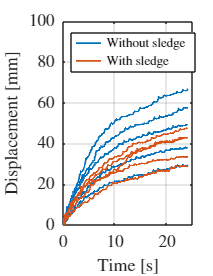

lgnd.ItemTokenSize(1) = 15;
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
ylim([0 100])
xlim([0 25])
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

directory = 'data/sand-no-sled/05Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_no(:,i) = data.data(:,2);
    y_sand_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/sand/05Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_with(:,i) = data.data(:,2);
    y_sand_with(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),sqrt((x_sand_no.*10).^2+(y_sand_no.*10).^2),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),sqrt(x_sand_with.^2+y_sand_with.^2),'Color',"#D95319",'LineWidth',1)
x0=10;
y0=10;
w=4.5;
h=5.85;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Without sledge', '', '','','','With sledge','Location','northwest','Interpreter','latex')

lgnd =   Legend (Without sledge, With sledge) with properties:

         String: {'Without sledge'  'With sledge'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 7.6500
       Position: [0.1670 0.7545 0.6970 0.1308]
          Units: 'normalized'

  Show all properties


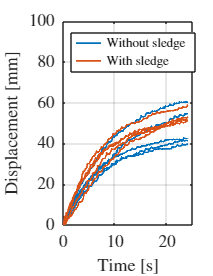

lgnd.ItemTokenSize(1) = 15;
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
ylim([0 100])
xlim([0 25])
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

directory = 'data/sand-no-sled/09Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_no(:,i) = data.data(:,2);
    y_sand_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/sand/09Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_with(:,i) = data.data(:,2);
    y_sand_with(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),sqrt((x_sand_no.*10).^2+(y_sand_no.*10).^2),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),sqrt(x_sand_with.^2+y_sand_with.^2),'Color',"#D95319",'LineWidth',1)
x0=10;
y0=10;
w=4.5;
h=5.85;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Without sledge', '', '','','','With sledge','Location','northwest','Interpreter','latex')

lgnd =   Legend (Without sledge, With sledge) with properties:

         String: {'Without sledge'  'With sledge'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 7.6500
       Position: [0.1670 0.7545 0.6970 0.1308]
          Units: 'normalized'

  Show all properties


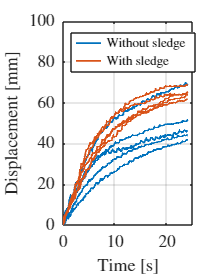

lgnd.ItemTokenSize(1) = 15;
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
ylim([0 100])
xlim([0 25])
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off